# Problem 4: Attitude dynamics

Student 1: Álvaro Reviriego Moreno

Student 2: Enrique Sentana Gómez

Data of the problem:

clear all;
close all;
muE = 398600; % mu Earth, km^3/s^2 
RE = 6371; % km
zetap = 600; % km
e = 0.1; % -
a =  (RE + zetap)/(1-e); % km 
w = [0,0,1]; % Equatorial orbit

## Nominal $\mathbf\omega_{b0}$

    In this section the goal is to obtain a function that computes the nominal angular velocity vector $$\vec{\omega_{b0}}$$ (in basis B0) to keep the Nadir orientation in the orbit defined by $\mu$, a, e, and $\vec{w}$ (unit vector along h), as a function of the true anomally which is going to be defined in this work as $\nu
$.

    For this purpose a function named nominal_hw is going to developed in such a way that introducing as inputs $\mu$, a, e, $\vec{w}$ and $\nu
$, it retunrns the value of $$\vec{\omega_{b0}}$$ in basis B0. First the function computes the orbit parameter also named as semi-latus rectum.


$$p = a(1-e^{2})$$


    Next, the angular momentum is obtained by getting its magnitude first and then projecting it onto $\vec{w}$.


$$h = \sqrt{p\mu}\\

\vec{h}=h\vec{w}$$


    Following, the angular rate at that instant needs to be obtained.


$$r = p/(1+ecos(\nu))
 $$



$$\dot{\theta} = h/r^2$$


    Finally, the nominal angular velocity vector can be computed.


$$\vec{\omega_{b0}} = \dot{\theta} \vec{w}$$


    To complete this task, the three components of the nominal angular velocity vector for a full orbit as a function of time is plotted. To do this, $\vec{\omega_{b0}$ is obtained for $\nu = [0\ 360]^\circ$.

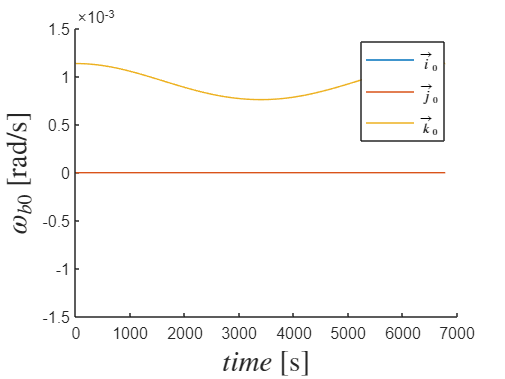

N = 360;
nu = linspace(0,2*pi,N); 
omega_b0 = zeros(3,N);
n = sqrt(muE/a^3);

for i = 1:N
   omega_b0(:,i) = nominal_hw(muE,a,e,w,nu(i));
   time(i) = nu(i)/n;
end 

figure(1)
hold on 
plot(time,omega_b0(1,:))
plot(time,omega_b0(2,:))
plot(time,omega_b0(3,:))
ylim([-1.5e-3,1.5e-3])
xlabel('$time$ [s]','Interpreter','latex','FontSize',18)
ylabel('$\omega_{b0}$ [rad/s]','Interpreter','latex','FontSize',18)
legend('$\vec i_{0}$','$\vec j_{0}$','$\vec k_{0}$','Interpreter','latex')

    As expected, only values for $$\vec{\omega_{b0}}$$ in the $\vec{k_{0}}$ direction are obtained, as due to the orbit with no inclination nor RAAN, the components for $\vec{i_{0}}$and $\vec{j_{0}}$are going to be 0. The oscillations in $\vec{k_{0}}$ are due to the spacecraft going from the periapsis to the apoapsis, where the higher values of $$\vec{\omega_{b0}}$$ correspond to the periapsis as the velocity in this point of the orbit is the highest and it will therefore have a larger angular velocity as well

## Euler angle derivatives

    For this section, the purpose is to develop a function that returns the time derivative of the three Euler angles of Sb with respect to Sℓ. The inputs required for this function are the orbit data, the true anomaly $\nu
$, the current angles and $$\vec{\omega_{b0}}$$ in S0. It is also set that the Euler angles and their derivatives habe to be a row vector.


$$\omega_{x} = \dot{\theta}cos(\psi)+\dot{\phi}sin(\theta)sin(\psi)\\

\omega_{y} = \dot{\theta}sin(\psi) - \dot{\phi}sin(\theta)cos(\psi)\\

\omega_{z} = \dot{\phi}cos(\theta) + \dot{\psi}$$


    It is also important to mention that within the function, to be able to obtain the time derivative of the three Euler angles of Sb with respect to Sℓ , the value of $ \vec{\omega_{\ell 0}$, which is obtained from the function nominal, needs to be sustracted to $ \vec{\omega_{b0}$ to obtain $ \vec{\omega_{b\ell}$, since$\vec{\omega_{b0}} = \vec{\omega_{b\ell}} + \vec{\omega_{\ell0}$, then $ \vec{\omega_{b\ell}$ needs to be rotated from basis S0 to basis Sℓ. Finally, the derivatives of the three Euler angles are obtained from the previous set of equations. Their expressions are as it follows.


$$\dot{\phi} = \frac{1}{sin(\theta)}(\frac{2 \omega_{x}}{sin(\psi)}- \omega_{y}cos(\psi) - \omega_{x}sin(\psi)$$



$$\dot{\theta} = \omega_{y} sin(\psi) + \omega_{x} cos(\psi) $$



$$\dot{\psi} = \omega_{z} - \dot{\phi} cos(\theta)$$


    To complete this part of the report, it is asked to show that by inputing the nominal $$\vec{\omega_{b0}}$$ obtained in the first section, the Euler angle derivatives are indeed 0 for the entire orbit, which are plotted in the figure below. As expected, the value of the three derivatives are 0 for the entire orbit since no angular momentum is being considered yet.

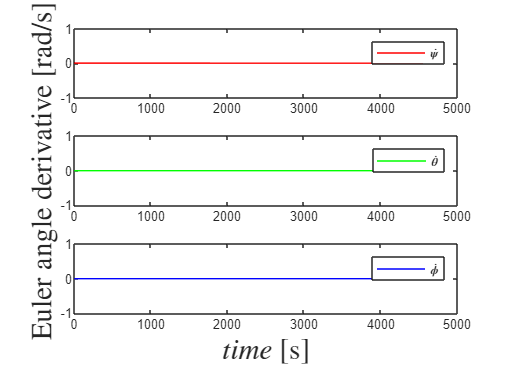

% nominal Euler angles
angles0= [pi/2 -pi/2 -pi/2]';

%danglesdt = zeros(3,N);
angles(:,1) = angles0;
danglesdt(:,1) = dangles_dt(muE,a,e,w,nu(1),angles(:,1),omega_b0(:,1));

for i=2:N
    angles(:,i) = angles(:,i-1)*(time(i)-time(i-1));
    danglesdt(:,i) = dangles_dt(muE,a,e,w,nu(i),angles(:,i),omega_b0(:,i));
end

figure
hold on
tiledlayout(3,1)
nexttile
plot(time,danglesdt(1,:),'r')
ylim([-1 1])
legend('$\dot{\psi}$','Interpreter','latex')

nexttile
plot(time,danglesdt(2,:),'g')
legend('$\dot{\theta}$','Interpreter','latex')
ylabel('Euler angle derivative [rad/s]','Interpreter','latex','FontSize',18)

nexttile
plot(time,danglesdt(3,:),'b')
xlabel('$time$ [s]','Interpreter','latex','FontSize',18)
legend('$\dot{\phi}$','Interpreter','latex')
hold off

## Wheel rates

    In this task, a function that obtains the required sacalar angular rates of the three wheels to maintain the desired angular velocity $$\vec{\omega_{b0}}$$ (in basis B0). The inputs for this purpose are the $\vec{w}$, the true anomally, the current Euler angles (of Sb with respect to Sℓ), and the angular momentum of the full assembly $H_{G0}^{b+w}$ (expressed in basis B0). Solving the equation below for $\vec{\omega_{wb}}$, one can obtain the vector containing the angular rates of the three wheels.


$$\vec{H_{G0}^{b+w}} = \textbf{I}_{G}^{b+w}\vec{\omega_{b0}} + \textbf{I}_{W}^{w}\vec{\omega_{wb}} = \textbf{const}\vert_{0}$$


% Individual wheel tensor of inertia
    r = 0.05; 
    m = 2; 
    Iw = m*r^2/2; 

    It is important to mentiont that to obtain the $\vec{\omega_{wb}}$, it is important to rotate $\vec{H_{G0}^{b+w}}$ and $$\vec{\omega_{b0}}$$ from basis Sb to basis B0. Also the following tensors of inertia for body and wheels are needed.

$\textbf{I}_{W}^{w}$ =$\left\lbrack \begin{array}{ccc}
I_{\textrm{WA}}  & 0 & 0\\
0 & I_{\textrm{WB}}  & 0\\
0 & 0 & I_{\textrm{WC}} 
\end{array}\right\rbrack {\underset{b}{\;} \;}_{\;} \textrm{kg}\cdot m^2$ , where $\textbf{I}_{Wi}^{w} = \frac{m_{i}r_{i}^{2}}{2}$

$\textbf{I}_{G}^{b+w}$ =$\left\lbrack \begin{array}{ccc}
180 & 0 & 0\\
0 & 220 & 0\\
0 & 0 & 300
\end{array}\right\rbrack {\underset{b}{\;} \;}_{\;} \textrm{kg}\cdot m^2$

    Also, it is required to set the $\vec{H_{G0}}$, where $H_{p} = 4.4\cdot 10^{-2} \ kg\cdot m^{2}/s$:


$$\vec{\textbf{H}_{G0}} = \textbf{I}_{G}\cdot n \vec{\textbf{k}_{0}} + Hp\vec{\textbf{j}_{0}}$$


    In the figure below, the evolution of the rotation of the three different wheels is plotted, as expected they oscillate through the entire orbit. It is interesting to mention that the period of the behaviour of the wheels is coincident to the orbital period of the spacecraft, which makes sense as they wheels are to mantain the specified orientation of the spacecraft for the entire time.

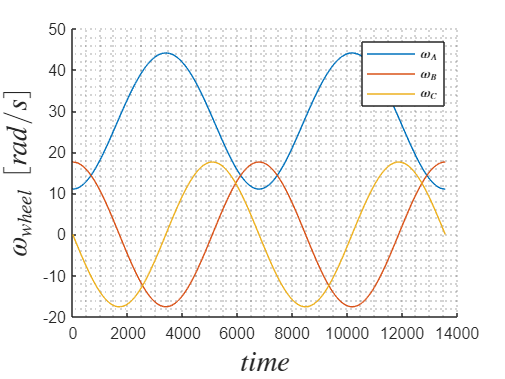

N = 720;
n = sqrt(muE/a^3);
timespan = linspace(0,4*pi/n,N);
nu = linspace(0,4*pi,N); 

I_g = diag([220,180,300]);

Hp = 4.4e-2;
H_G0_aux = I_g*n*[0 0 1]';

H_G0 = [0;Hp;0] + H_G0_aux;

for i=1:N
    omega_b0 = nominal_hw(muE,a,e,w,nu(i));
    [omegaA(i),omegaB(i),omegaC(i)] = wheels(w,nu(i),angles0,omega_b0,H_G0);
end

figure
hold on
grid minor
plot(timespan,omegaA)
plot(timespan,omegaB)
plot(timespan,omegaC)
xlabel('$time \ [s]$','Interpreter','latex','FontSize',18)
ylabel('$\omega_{wheel} \ [rad/s]$','Interpreter','latex','FontSize',18)
legend('$\omega_{A}$','$\omega_{B}$','$\omega_{C}$','Interpreter','latex')
hold off

## Broken wheels

    In this final section, the motors driving the three wheels break and therefore they stop completely. Thus, now the roation of the spacecraft cannot be cancelled and it will have an angular velocity. It is now required to propagate the attitude of the spacecraft through two full orbits using ode45. For this purpose, two new functions need to be created.

    The first one is called [broken](matlab:open('./broken.m')), a function devoted to give as an output $\vec{\omega_{b0}}$, using as inputs $\vec{w}, \nu, \vec{H_{G0}}$, and the three euler angles. Where $\vec{\omega_{b0}}$ is obtained from $\vec{H_{G0}} = \textbf{I}_{G}\cdot \vec{\omega_{b0}}$, taking into account that $\vec{H_{G0}}$ from basis S0 to basis Sb.

    Then a second funciton called dX_dt_attitude_hwk4 needs to be created. The purpose os this function is to introduce the evolution of the attitude of the spacecraft in ode45. In this function the state vector is set to be $X = [\nu, \psi, \theta, \phi]$. First the derivative of the true anomally with respect to time is computed through the norm of the output of the function nominal_hw. And then the derivative of the euler angles is obtained using the already commented function dangles_dt, the $\vec{\omega_{b0}}$ required as input is obtained with the function broken just explained.

    In this way, the four elements of the stet vector X are propagated for a given dt. Finally, the three euler angles $(\psi, \theta, \phi)$ for the two full orbits are plotted below.

    The behaviour of both $\psi $ and $\phi $ are similar, as they keep increasing their values with some oscillations. This is due to the contributions in the$\vec{j_{0}}$ and $\vec{k_{0}}$ directions on the $\vec{H_{G0}}$, that contribute in increasing $\vec{\omega_{b0}}$ along the orbit, affecting also the time derivative of these euler angles.

    It is also interesting to comment that the completely non-symmetric tensor of inertia of the spacecraft contributes to the oscillations and strange shape of the evolutions of the three euler angles.

    Also, as it can be seen $\theta$ slightly oscillates around its initial value $-\pi/2$, this is due to the fact that the angular momentum affecting the nutation is clearly not as large as the contributions to precession and spin. Therefore its evolution can be considered null, as the small oscillations present are also due to numerical effects coming from the propagation of the attitude using ode45, apart from the contributions from the angular momentum and the characteristics of the tensor of inertia discussed previously.

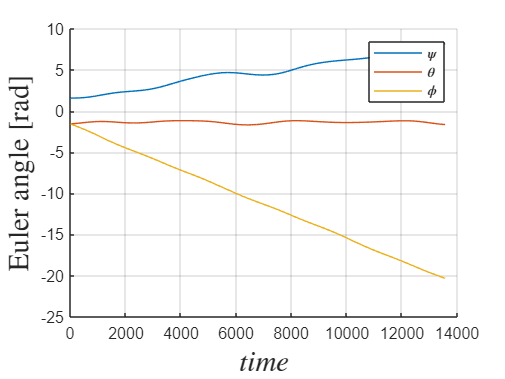

% State vector is X = [nu, psi, theta, phi]
[t,X] = ode45(@(t,X)dX_dt_attitude_mafia(muE,a,e,w,X,H_G0),[0,4*pi*sqrt(a^3/muE)],[0;angles0]);

figure
hold on
grid on
% plot(t,X(:,1))
plot(t,X(:,2))
plot(t,X(:,3))
plot(t,X(:,4))
xlabel('$time$','Interpreter','latex','FontSize',18)
ylabel('Euler angle [rad]','Interpreter','latex','FontSize',18)
legend('$\psi$','$\theta$','$\phi$','Interpreter','latex')
hold off